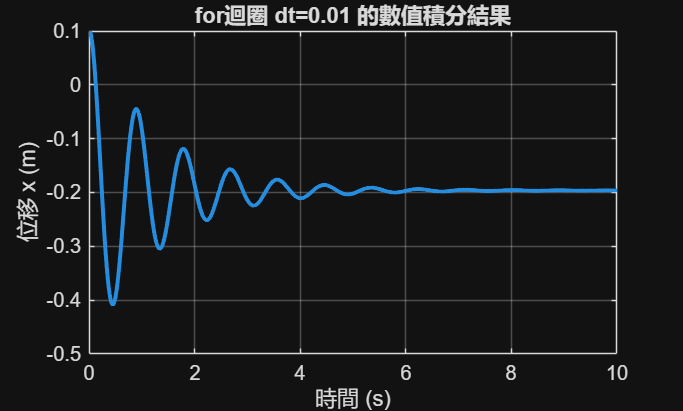

% 參數設定
m = 1;      % 質量 (kg)
k = 50;     % 彈簧常數 (N/m)
c = 2;      % 阻尼係數 (N·s/m)
g = 9.81;   % 重力加速度 (m/s^2)

% 初始條件
x0 = 0.1;   % 初始位移 (m)
v0 = 0;     % 初始速度 (m/s)

% 時間設定
dt = 0.01;          % 積分步長
Tend = 10;          % 模擬總時間
N = floor(Tend/dt); % 步數
t = (0:N)*dt;       % 時間向量

% 預先配置陣列
x = zeros(1, N+1);
v = zeros(1, N+1);

% 初始值
x(1) = x0;
v(1) = v0;

% for 迴圈積分 (Euler 法)
for i = 1:N
    % 加速度 a = d^2x/dt^2
    a = (-c*v(i) - k*x(i) - m*g)/m;
    
    % 更新速度與位移
    v(i+1) = v(i) + a*dt;
    x(i+1) = x(i) + v(i)*dt;
end

% 繪圖
figure;
plot(t, x, 'LineWidth', 2);
xlabel('時間 (s)');
ylabel('位移 x (m)');
title('for迴圈 dt=0.01 的數值積分結果');
grid on;